clear;
clc;
format long
%% Load Dataset
Xtrain = load('Xtrain.mat').Xtrain;
Ytrain = load('Ytrain.mat').Ytrain;
Xtest = load('Xtest.mat').Xtest;
Ytest = load('Ytest.mat').Ytest;
cvKF5 = load('cvKF5.mat','cvKF5').cvKF5;
cvKF10 = load('cvKF10.mat','cvKF10').cvKF10;
cvKF20 = load('cvKF20.mat','cvKF20').cvKF20;
%% Load MRMR
MRMR = load('MRMR.mat').MRMR;
idxMRMR = MRMR(1,:);
scores = MRMR(2,:);
%% K vs Num. Features (K-Fold = 5)
nbMRMR_5 = zeros(12,1);
AUC_5 = zeros(12,1);
F1_5 = zeros(12,1);

for f=1:12
    
    nbMRMR_CV = fitcnb(Xtrain(:,idxMRMR(1:f)),Ytrain,'CVPartition',cvKF5);
    [nbMRMR_pred, scores] = kfoldPredict(nbMRMR_CV);
    nbMRMR_5(f) = mean(Ytrain == nbMRMR_pred);
        
    [~,~,~,AUCnb_n] = perfcurve(Ytrain,scores(:,1),'Necrosis');
    [~,~,~,AUCnb_s] = perfcurve(Ytrain,scores(:,2),'Stroma');
    [~,~,~,AUCnb_t] = perfcurve(Ytrain,scores(:,3),'Tumor');
    AUC_5(f) = (AUCnb_n + AUCnb_s + AUCnb_t)/3;
    tpNk = sum(ismember(Ytrain,'Necrosis') & ismember(nbMRMR_pred,'Necrosis'));
        tpSk = sum(ismember(Ytrain,'Stroma') & ismember(nbMRMR_pred,'Stroma'));
        tpTk = sum(ismember(Ytrain,'Tumor') & ismember(nbMRMR_pred,'Tumor'));
        fpNk = sum(ismember(nbMRMR_pred,'Necrosis')) - tpNk;
        fpSk = sum(ismember(nbMRMR_pred,'Stroma')) - tpSk;
        fpTk = sum(ismember(nbMRMR_pred,'Tumor')) - tpTk;
        fnNk = sum(ismember(Ytrain, 'Necrosis')) - tpNk;
        fnSk = sum(ismember(Ytrain, 'Stroma')) - tpSk;
        fnTk = sum(ismember(Ytrain, 'Tumor')) - tpTk;
        f1Nk = tpNk/(tpNk + (fpNk+fnNk)/2);
        f1Sk = tpSk/(tpSk + (fpSk+fnSk)/2);
        f1Tk = tpTk/(tpTk + (fpTk+fnTk)/2);
        F1_5(f) = (f1Nk + f1Sk + f1Tk)/3;

        
end
%% Heatmap Accuracy
% xvals_numF = num2cell(Ks);
% yvals_k = num2cell([1:12]);
figure;
h5 = heatmap(nbMRMR_5,'Colormap', jet, 'CellLabelColor','none');
title('Naive Bayes: Accruacy 5-Fold');
% h5.XLabel = 'K_K_N_N';
% h5.YLabel = 'Num of Features';

%% Heatmap AUC
figure;
h = heatmap(AUC_5,'Colormap', jet, 'CellLabelColor','none');
title('Naive Bayes: AUC 5-Fold');
% h.XLabel = 'K_K_N_N';
% h.YLabel = 'Num of Features';
%% Heatmap F1
figure;
h = heatmap(F1_5,'Colormap', jet, 'CellLabelColor','none');
title('Naive Bayes: F1 Score 5-Fold');
% h.XLabel = 'K_K_N_N';
% h.YLabel = 'Num of Features';

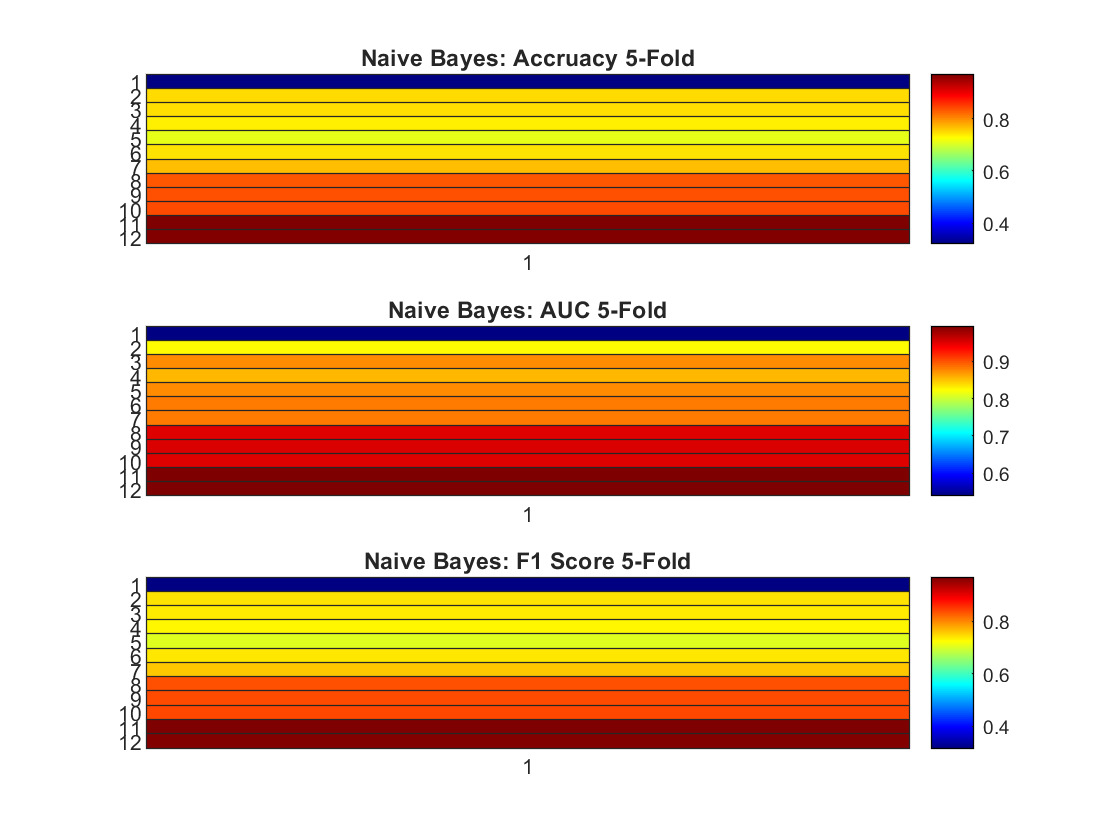

figure;

subplot(3,1,1);
heatmap(nbMRMR_5,'Colormap', jet, 'CellLabelColor','none');
title('Naive Bayes: Accruacy 5-Fold');

subplot(3,1,2);
heatmap(AUC_5,'Colormap', jet, 'CellLabelColor','none');
title('Naive Bayes: AUC 5-Fold');

subplot(3,1,3);
heatmap(F1_5,'Colormap', jet, 'CellLabelColor','none');
title('Naive Bayes: F1 Score 5-Fold');

## K vs Num. Features (K-Fold = 10)


nbMRMR_10 = zeros(12,1);
AUC_10 = zeros(12,1);
F1_10 = zeros(12,1);
for f=1:12
    
    nbMRMR_CV = fitcnb(Xtrain(:,idxMRMR(1:f)),Ytrain,'CVPartition',cvKF10);
    [nbMRMR_pred, scores] = kfoldPredict(nbMRMR_CV);
    nbMRMR_10(f) = mean(Ytrain == nbMRMR_pred);
        
    [~,~,~,AUCnb_n] = perfcurve(Ytrain,scores(:,1),'Necrosis');
    [~,~,~,AUCnb_s] = perfcurve(Ytrain,scores(:,2),'Stroma');
    [~,~,~,AUCnb_t] = perfcurve(Ytrain,scores(:,3),'Tumor');
    AUC_10(f) = (AUCnb_n + AUCnb_s + AUCnb_t)/3;
    tpNk = sum(ismember(Ytrain,'Necrosis') & ismember(nbMRMR_pred,'Necrosis'));
        tpSk = sum(ismember(Ytrain,'Stroma') & ismember(nbMRMR_pred,'Stroma'));
        tpTk = sum(ismember(Ytrain,'Tumor') & ismember(nbMRMR_pred,'Tumor'));
        fpNk = sum(ismember(nbMRMR_pred,'Necrosis')) - tpNk;
        fpSk = sum(ismember(nbMRMR_pred,'Stroma')) - tpSk;
        fpTk = sum(ismember(nbMRMR_pred,'Tumor')) - tpTk;
        fnNk = sum(ismember(Ytrain, 'Necrosis')) - tpNk;
        fnSk = sum(ismember(Ytrain, 'Stroma')) - tpSk;
        fnTk = sum(ismember(Ytrain, 'Tumor')) - tpTk;
        f1Nk = tpNk/(tpNk + (fpNk+fnNk)/2);
        f1Sk = tpSk/(tpSk + (fpSk+fnSk)/2);
        f1Tk = tpTk/(tpTk + (fpTk+fnTk)/2);
        F1_10(f) = (f1Nk + f1Sk + f1Tk)/3;
        
end
%% Heatmap Accuracy
% xvals_numF = num2cell(Ks);
% yvals_k = num2cell([1:12]);
figure;
h5 = heatmap(nbMRMR_10, 'Colormap', jet, 'CellLabelColor','none');
title('Naive Bayes: Accuracy 10-Fold');
% h5.XLabel = 'K_K_N_N';
h5.YLabel = 'Num of Features';
%% Heatmap AUC
figure;
h2 = heatmap(AUC_10, 'Colormap', jet, 'CellLabelColor','none');
title('Naive Bayes: AUC 10-Fold');
% h.XLabel = 'K_K_N_N';
h2.YLabel = 'Num of Features';
%% Heatmap F1
figure;
h = heatmap(F1_10, 'Colormap', jet, 'CellLabelColor','none');
title('Naive Bayes: F1 Score 10-Fold');
% h.XLabel = 'K_K_N_N';
h.YLabel = 'Num of Features';

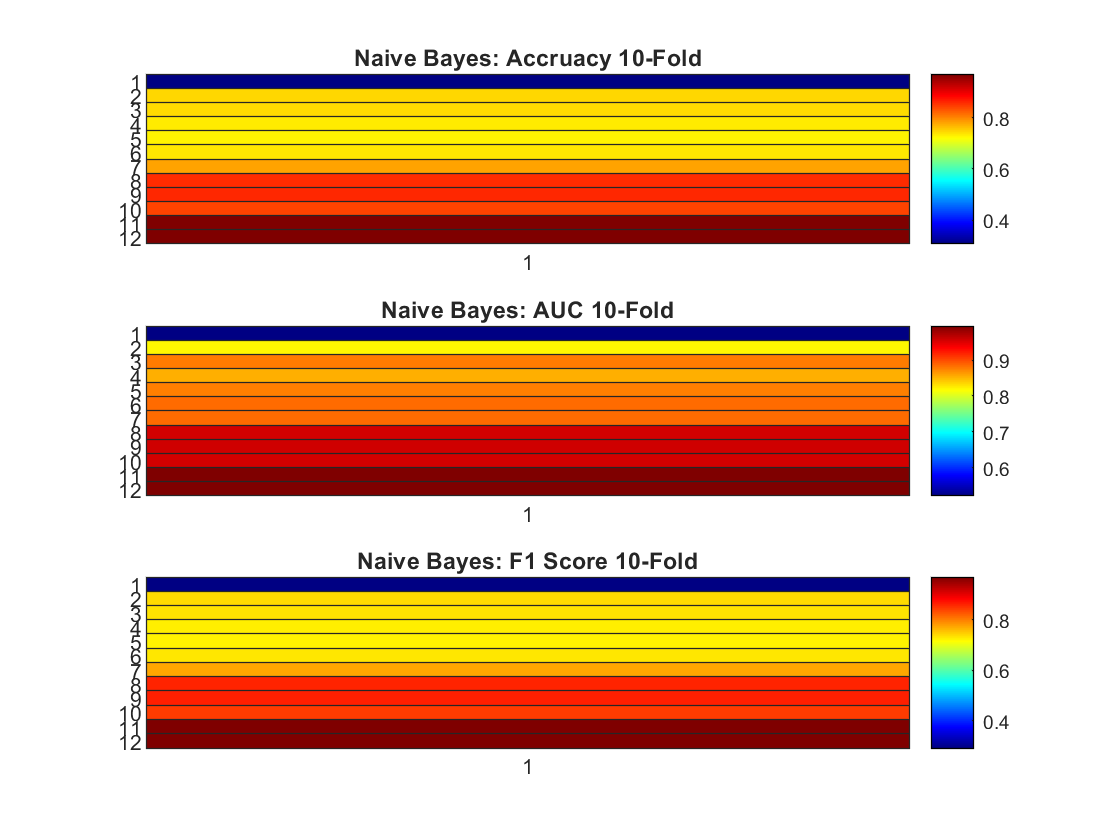

figure;

subplot(3,1,1);
heatmap(nbMRMR_10,'Colormap', jet, 'CellLabelColor','none');
title('Naive Bayes: Accruacy 10-Fold');

subplot(3,1,2);
heatmap(AUC_10,'Colormap', jet, 'CellLabelColor','none');
title('Naive Bayes: AUC 10-Fold');

subplot(3,1,3);
heatmap(F1_10,'Colormap', jet, 'CellLabelColor','none');
title('Naive Bayes: F1 Score 10-Fold');

## External Validtion


nbMRMR_flat_1 = reshape(nbMRMR_10,[],1);
nbMRMR_flat = sort(unique(nbMRMR_flat_1), 'descend');
fs = [];
nbMRMR_CV_preds = [];
for a=1:length(nbMRMR_flat)
    inds = find(nbMRMR_10 == nbMRMR_flat(a));
    for i = 1:length(inds)
        fs = [fs, inds(i)];
        nbMRMR_CV_preds = [nbMRMR_CV_preds, nbMRMR_flat(a)];
    end
end
%%
nbMRMR_preds = [];
for i=1:length(fs)
    f = fs(i);
    nbMRMR = fitcnb(Xtrain(:,idxMRMR(1:f)),Ytrain);
    pred = predict(nbMRMR, Xtest(:,idxMRMR(1:f)));
    nbMRMR_preds = [nbMRMR_preds, mean(pred==Ytest)]; % accuracy
    
end


## Plot Acuracy

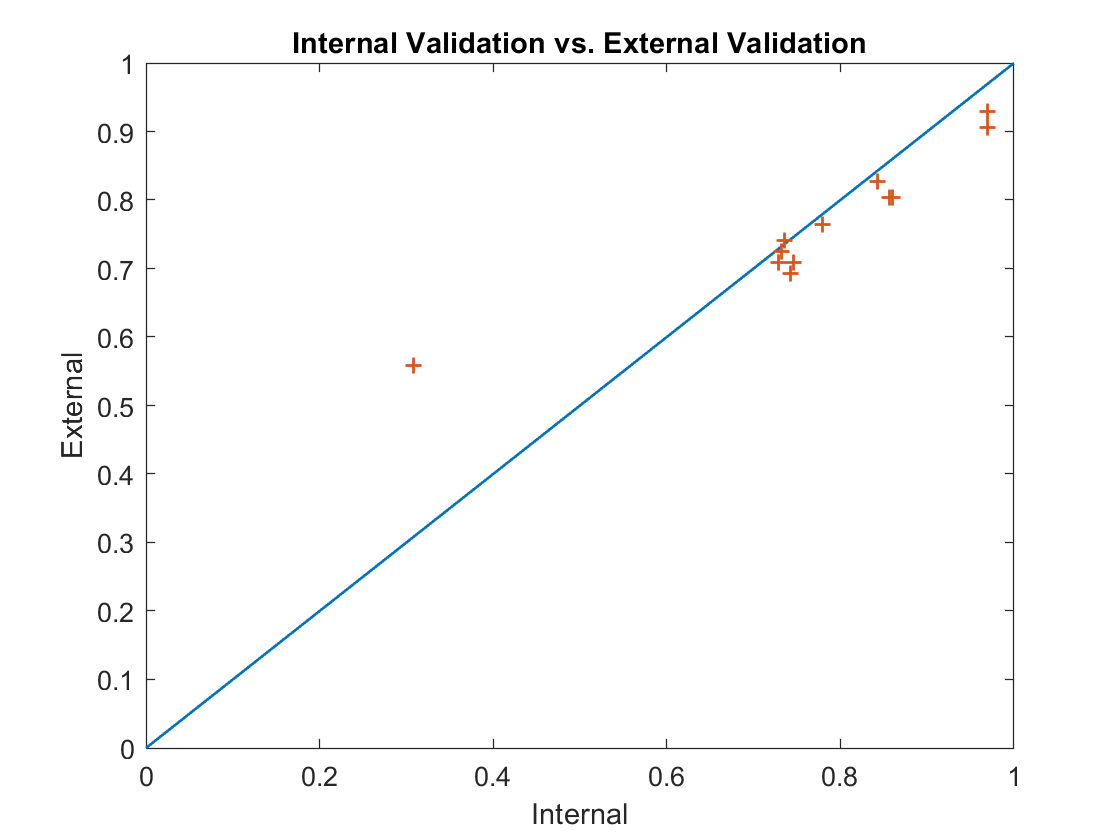


figure;
x = [0:1];
y = x;
plot(x, y,'Linewidth',1);
hold on

scatter(nbMRMR_CV_preds,nbMRMR_preds,'+','Linewidth',1);

xlabel('Internal');
ylabel('External');

title('Internal Validation vs. External Validation');


%12
master_nb = [nbMRMR_preds.', fs.'];
master_nb = sortrows(master_nb,1,'descend');
bf = master_nb(1,2);
nbMRMR = fitcnb(Xtrain(:,idxMRMR(1:bf)),Ytrain);
[pred,score] = predict(nbMRMR, Xtest(:,idxMRMR(1:bf)));
acc = mean(pred==Ytest) * 100 % accuracy
figure;
cm = confusionchart(cellstr(Ytest),pred);
title(['Naive Bayes: ', num2str(acc), '%'])

figure;
subplot(2,1,1);
x = [0:1];
y = x;
plot(x, y,'Linewidth',1);
hold on

scatter(nbMRMR_CV_preds,nbMRMR_preds,'+','Linewidth',1);

xlabel('Internal');
ylabel('External');

title('Internal Validation vs. External Validation');

subplot(2,1,2);
master_nb = [nbMRMR_preds.', fs.'];
master_nb = sortrows(master_nb,1,'descend');
bf = master_nb(1,2);
nbMRMR = fitcnb(Xtrain(:,idxMRMR(1:bf)),Ytrain);
[pred,score] = predict(nbMRMR, Xtest(:,idxMRMR(1:bf)));
acc = mean(pred==Ytest) * 100 % accuracy

acc =   92.913385826771659


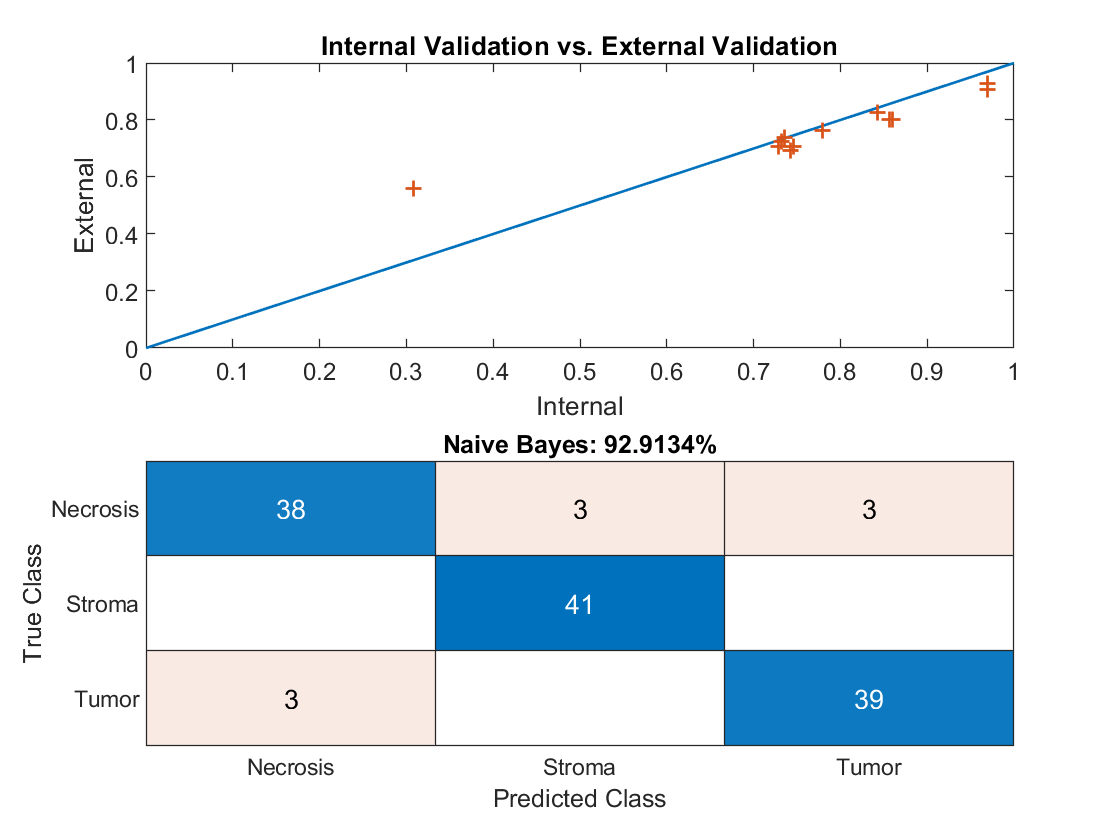

confusionchart(cellstr(Ytest),pred);
title(['Naive Bayes: ', num2str(acc), '%'])


[X_nb_n,Y_nb_n,T,AUCnb_n] = perfcurve(Ytest,score(:,1),'Necrosis');
[X_nb_s,Y_nb_s,T,AUCnb_s] = perfcurve(Ytest,score(:,2),'Stroma');
[X_nb_t,Y_nb_t,T,AUCnb_t] = perfcurve(Ytest,score(:,3),'Tumor');
%%
figure;
plot(X_knn_n, Y_knn_n,'Linewidth',1.5)
hold on
plot(X_rf_n, Y_rf_n,'Linewidth',1.5)
plot(X_nb_n, Y_nb_n,'Linewidth',1.5)
title('AUC-Necrosis');
legend('KNN','Random Forest','Naive Bayes');
